a = [1 -3; 1 -1; 1 1; 1 3];
y = [8 23 28 34]';


r = inv(a.' * a) * (a.' *y)

r =    23.2500
    4.1500


% or, r can also be defined this way: r = mldivide(a.'*a, a.'*y)

a_2 = [1 -3 9; 1 -1 1; 1 1 1; 1 3 9];
r_2 = inv(a_2.' *a_2) * (a_2.' * y);

a_3 = [1 -3 9 -27; 1 -1 1 -1; 1 1 1 1; 1 3 9 27];
r_3 = inv(a_3.' *a_3) * (a_3.' * y);

coded_humidity = [-3 -1 1 3];
electrical_conductivity = [8 23 28 34];
scatter(coded_humidity,electrical_conductivity);
hold on 

x = linspace(-5,5)

x =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


y = r(1,:) + r(2,:)*x

y =     2.5000    2.9192    3.3384    3.7576    4.1768    4.5960    5.0152    5.4343    5.8535    6.2727    6.6919    7.1111    7.5303    7.9495    8.3687    8.7879    9.2071    9.6263   10.0455   10.4646   10.8838   11.3030   11.7222   12.1414   12.5606   12.9798   13.3990   13.8182   14.2374   14.6566   15.0758   15.4949   15.9141   16.3333   16.7525   17.1717   17.5909   18.0101   18.4293   18.8485   19.2677   19.6869   20.1061   20.5253   20.9444   21.3636   21.7828   22.2020   22.6212   23.0404


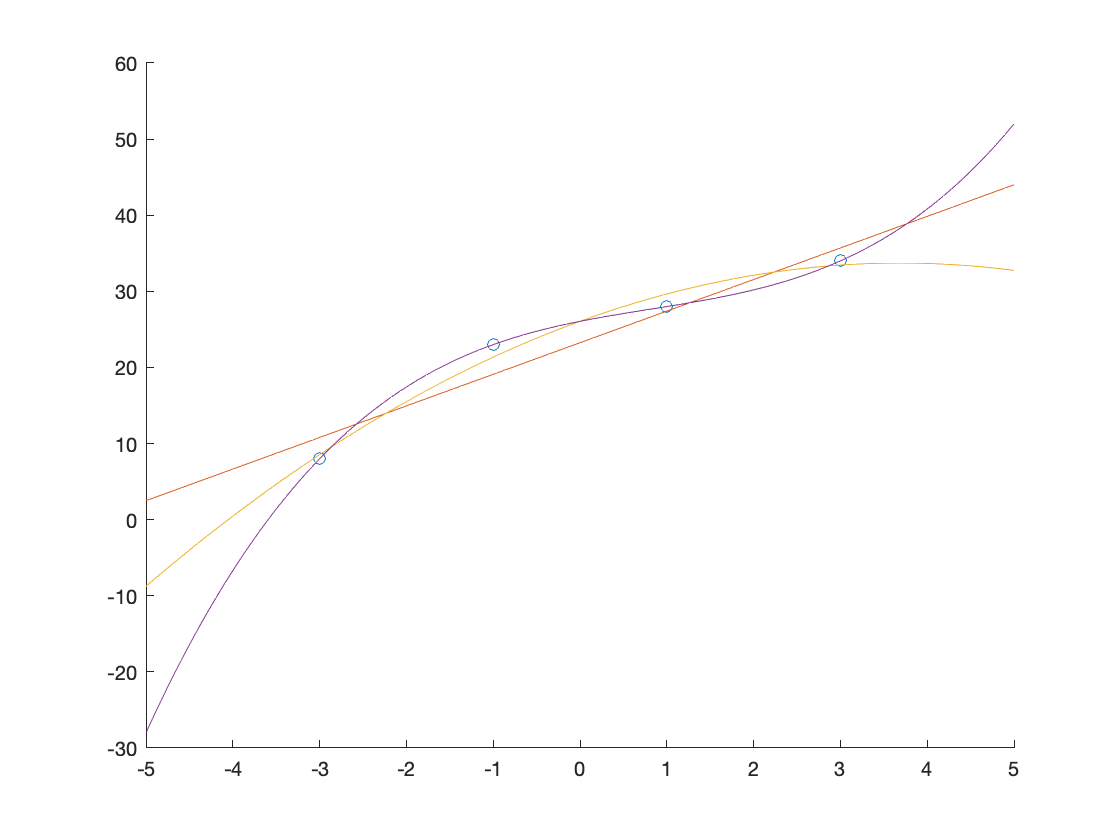

plot(x, y)



y_2 = r_2(1,:) + r_2(2,:)*x + r_2(3,:)*x.^2;
plot(x,y_2)

y_3 = r_3(1,:) + r_3(2,:)*x + r_3(3,:)*x.^2 + r_3(4,:)*x.^3;
plot(x,y_3)